Мухин Георгий РЛ6-31

Задача:

Необходимо отрисовать для электрона локализованного в одномерной бесконечно глубокой яме 10 нм график пси функции от координаты (для основного состояния и 24-го возбужденного). Сравнить графики полученный на основе аналитического решения уравнения Шрёдингера с результатами работы встроенной MATLAB-функции eig.

Теория:

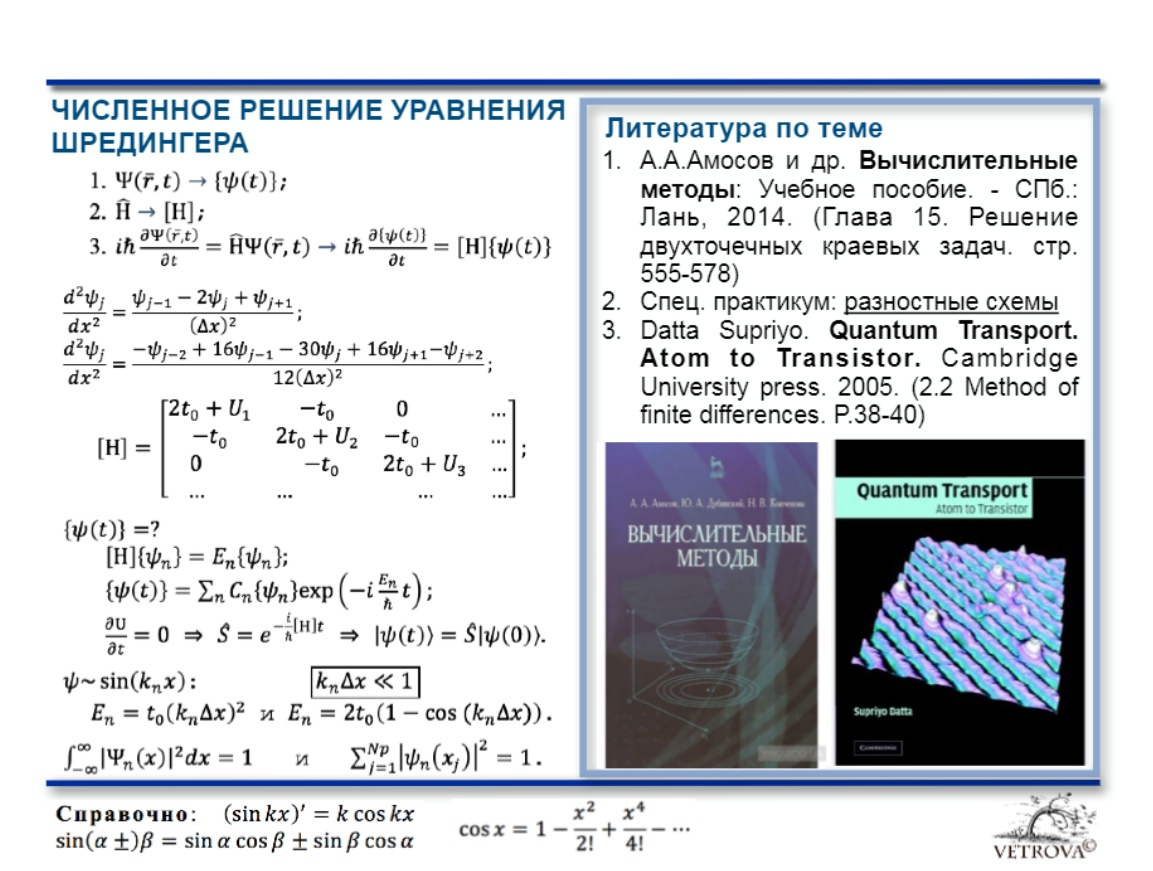

В этом методе мы с помощью функции eig сможем получить собственные значения, соответсветствующие 1 и 25 энергетическому уровню.

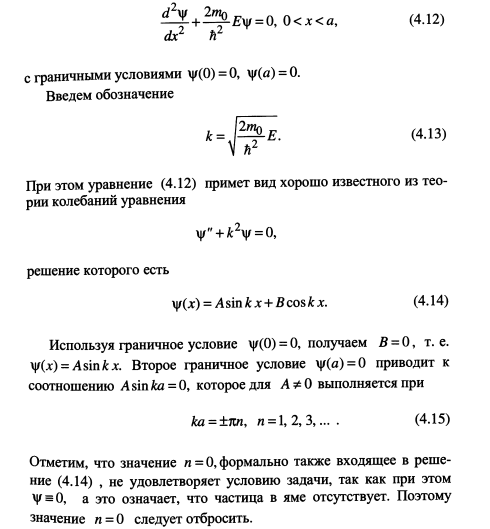

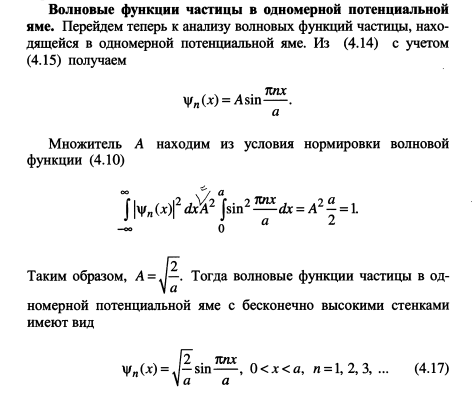

clc;
clear;
close all;
datetime('now')

ans = datetime
   02-Dec-2021 10:36:27


load("constans.mat");
L = 101e-10;
Np = 100;
n=1:100;
A = 2/L;
dx = L / (Np+1);
t0 = hbar^2/(2*m0 * dx^2)

t0 = 6.1043e-19

H = zeros(Np, Np);
[H]= create_Hamiltonian(Np, H, t0);
[Psi, En] = eig(H);
x = linspace(0, L, Np);
norma_En = sum(abs(Psi(1:end,1:end).^2))

norma_En =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


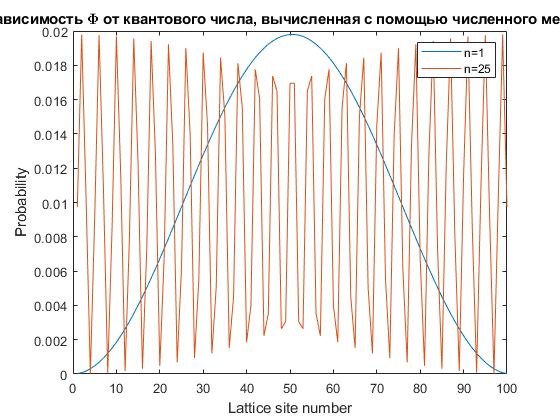

quantum_states=linspace(1,600,600);
plot(n, abs(Psi(1:end, 1).^2));
hold on
plot(n, abs(Psi(1:end, 25).^2));
hold off
title('Зависимость \Phi от квантового числа, вычисленная с помощью численного метода')
xlabel('Lattice site number');
ylabel('Probability')
legend('n=1','n=25');

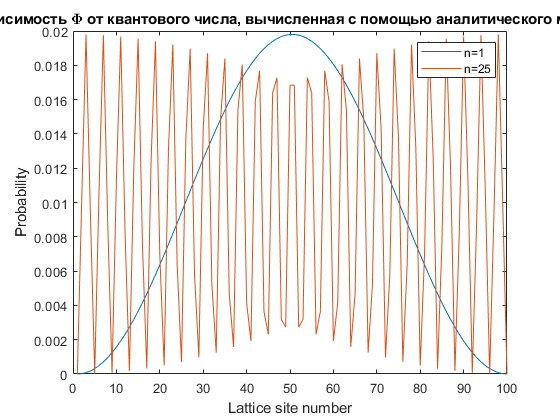

plot(n, dx.*A*sin((pi * 1/L)  * x).^2);
hold on;

plot(n, dx*A*abs(sin((pi * 25/ L) * x).^2));
hold off
legend('n=1','n=25')
xlabel('Lattice site number');
ylabel('Probability')
title('Зависимость \Phi от квантового числа, вычисленная с помощью аналитического метода')

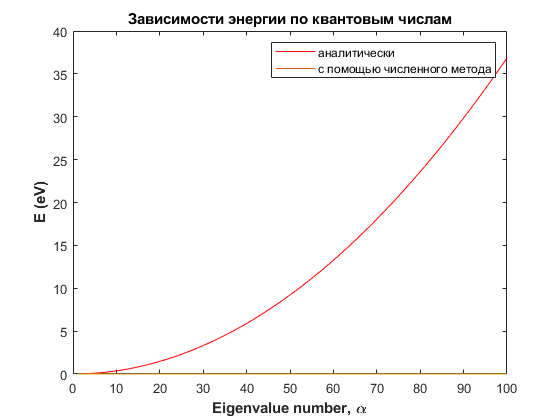

figure
E=pi.^2.*hbar.^2*n.^2/(2*m0*L^2)*J2eV;
En_dig = diag(En)*J2eV;
plot(n, E,"Color",'red');
hold on;
plot(n, En_dig);
title('Зависимости энергии по квантовым числам')
legend('аналитически','с помощью численного метода')
xlabel('Eigenvalue number, \alpha', FontWeight='bold');
ylabel('E (eV)', FontWeight='bold')
hold off;

%--------------------------------------------------------------------
%values for table
format short
Ah=[E(1) E(2) E(3) E(25)]

Ah =     0.0037    0.0147    0.0332    2.3039


E=E.*1e3;
deltaE=[(E(2)-E(1)) ceil(E(3)-E(2)) (E(4)-E(3)) kT*10^3]

deltaE =    11.0586   19.0000   25.8035   25.8520


deltaE=int8(deltaE)

deltaE = 1×4 int8 row vector
   11   19   26   26


t0=t0*J2eV

t0 = 3.8100

function [H] = create_Hamiltonian(Np, H, t0)
for i = 1:Np
    for j = 1:Np
        if i == 1
            if i == j
                H(i, j) = 2*t0;
                    H(i, j + 1) = -t0;
            end
        end
        if and(i ~= 1, i ~= Np )
            if i == j
                H(i, j) = 2*t0 ;
                H(i, j - 1) = -t0;
                H(i, j + 1) = -t0;
            end
        end
        if i == Np
            if i == j
                H(i, j) = 2*t0 ;
                H(i, j - 1) = -t0;
            end
        end
    end
end
end
